clc;
clear;
close all;

%% ============================================================
%  PARÂMETROS FÍSICOS DA PLANTA
% =============================================================

m  = 0.498;
g  = 9.81;
l  = 0.10;
I  = 0.00498;

mw = 0.117;
Rw = 0.126;
Iw = 9.28746e-4;

k  = 0.02938;
r  = 7.0518;

%% ============================================================
%  MODELO EM ESPAÇO DE ESTADOS
% =============================================================

A = [0         1        0;
     m*g*l/I   0        k^2/(I*r);
     0         0       -k^2/(Iw*r)];

B = [0;
    -k/(I*r);
     k/(Iw*r)];

Aa = [A      zeros(3,1);
      0 0 -1 0];

Ba = [B;
      0];

%% ============================================================
%  DISCRETIZAÇÃO DO MODELO AUMENTADO
% =============================================================

Ts = 0.01;

sysc = ss(Aa, Ba, eye(4), zeros(4,1));
sysd = c2d(sysc, Ts, 'tustin');

Ad = sysd.A;
Bd = sysd.B;

%% ============================================================
%  GANHO LQR DISCRETO
% =============================================================

Kd = [-247.8615  -26.3120  -0.1175   0.0107];

%% ============================================================
%  PARÂMETROS DO SWING-UP POR ENERGIA
% =============================================================

uMax = 12;

Ebaixo = -2*m*g*l;
Etopo = 0;
DeltaE = abs(Ebaixo - Etopo);

excessoEnergia = 0.15;

Eref = Etopo + excessoEnergia*DeltaE;

kSwing = uMax / DeltaE;

polaridadeSwing = -1;

%% ============================================================
%  REGIÃO DE CAPTURA DO LQR E FREIO
% =============================================================

thetaLQR    = deg2rad(12);
thetaDotLQR = deg2rad(120);

thetaCaptura = deg2rad(90);

%% ============================================================
%  SIMULAÇÃO
% =============================================================

Tsim = 40;
N = round(Tsim/Ts);

t = (0:N-1)*Ts;

x = zeros(4,N);
u = zeros(1,N);
E = zeros(1,N);
modo = zeros(1,N);

x(:,1) = [pi; 0; 0; 0];

lqrAtivo = false;

%% ============================================================
%  LOOP DE SIMULAÇÃO
% =============================================================

for i = 1:N-1

    theta    = x(1,i);
    thetaDot = x(2,i);
    omega    = x(3,i);
    xi       = x(4,i);

    theta = atan2(sin(theta), cos(theta));
    x(1,i) = theta;

    E(i) = 0.5*I*thetaDot^2 + m*g*l*(cos(theta) - 1);

    %% ========================================================
    %  VERIFICAÇÃO PARA ENTRADA NO LQR
    % =========================================================

    if ~lqrAtivo
        if abs(theta) < thetaLQR && abs(thetaDot) < thetaDotLQR
            lqrAtivo = true;

            x(4,i) = 0;
            xi = 0;
        end
    end

    %% ========================================================
    %  CÁLCULO DO CONTROLE
    % =========================================================

    if lqrAtivo

        %% CONTROLE LQR

        u(i) = -Kd*x(:,i);

        modo(i) = 2;

    else

        %% VERIFICA SE ENTRA NA ETAPA DE CAPTURA/FREIO

        if abs(theta) < thetaCaptura && abs(thetaDot) >= thetaDotLQR

            u(i) = uMax * sign(thetaDot);

            modo(i) = 1;

        else

            %% CONTROLE SWING-UP POR ENERGIA

            erroE = E(i) - Eref;

            sinal = sign(thetaDot);

            if sinal == 0
                sinal = sign(theta);
            end

            if sinal == 0
                sinal = 1;
            end

            u(i) = -polaridadeSwing * kSwing * erroE * sinal;

            modo(i) = 0;

        end

    end

    u(i) = max(min(u(i), uMax), -uMax);

    %% ========================================================
    %  ATUALIZAÇÃO DOS ESTADOS
    % =========================================================

    if lqrAtivo

        x(:,i+1) = Ad*x(:,i) + Bd*u(i);

    else

        thetaDDot = (m*g*l/I)*sin(theta) + ...
                    (k^2/(I*r))*omega - ...
                    (k/(I*r))*u(i);

        omegaDot = -(k^2/(Iw*r))*omega + ...
                    (k/(Iw*r))*u(i);

        xiDot = -omega;

        x(1,i+1) = x(1,i) + Ts*x(2,i);
        x(2,i+1) = x(2,i) + Ts*thetaDDot;
        x(3,i+1) = x(3,i) + Ts*omegaDot;
        x(4,i+1) = x(4,i) + Ts*xiDot;

    end

end

E(end) = E(end-1);
u(end) = u(end-1);
modo(end) = modo(end-1);

%% ============================================================
%  INFORMAÇÕES DO GANHO CALCULADO
% =============================================================

disp('===============================================');

disp('PARÂMETROS DO SWING-UP');

PARÂMETROS DO SWING-UP


disp('===============================================');

disp(['Energia inferior Ebaixo     = ', num2str(Ebaixo), ' J']);

Energia inferior Ebaixo     = -0.97708 J


disp(['Energia do topo Etopo       = ', num2str(Etopo), ' J']);

Energia do topo Etopo       = 0 J


disp(['DeltaE                     = ', num2str(DeltaE), ' J']);

DeltaE                     = 0.97708 J


disp(['Excesso de energia         = ', num2str(excessoEnergia*100), ' %']);

Excesso de energia         = 15 %


disp(['Energia desejada Eref      = ', num2str(Eref), ' J']);

Energia desejada Eref      = 0.14656 J


disp(['kSwing calculado           = ', num2str(kSwing), ' V/J']);

kSwing calculado           = 12.2815 V/J


disp(['Polaridade do swing-up     = ', num2str(polaridadeSwing)]);

Polaridade do swing-up     = -1


disp('===============================================');

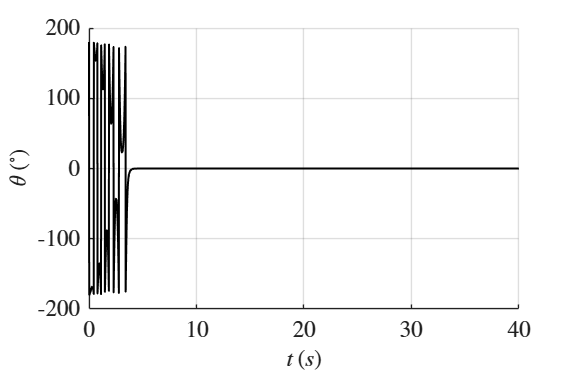


%% ============================================================
%  GERAÇÃO DOS GRÁFICOS EM PDF
% =============================================================

theta_graus = rad2deg(x(1,:));
thetaDot_graus = rad2deg(x(2,:));

picturewidth = 20;
hw_ratio = 0.65;

%% Figura 1 - Ângulo

hfig = figure;

plot(t, theta_graus, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\theta \, (^\circ)$', 'Interpreter', 'latex');

grid on;

fname = 'resultado_theta_simulado';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

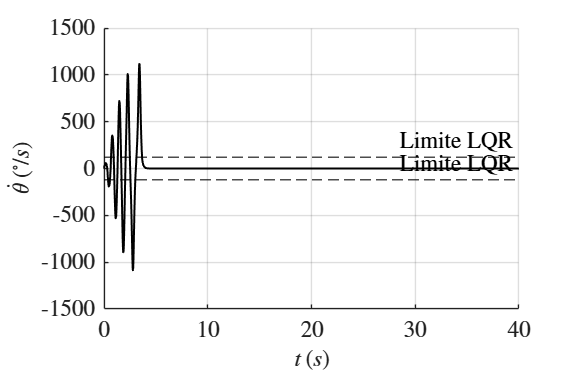


%% Figura 2 - Velocidade angular do corpo

hfig = figure;

plot(t, thetaDot_graus, 'k-', 'LineWidth', 1.5);
hold on;
yline(rad2deg(thetaDotLQR), '--k', 'Limite LQR', 'LineWidth', 1.2);
yline(-rad2deg(thetaDotLQR), '--k', 'Limite LQR', 'LineWidth', 1.2);
hold off;

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\dot{\theta} \, (^\circ/s)$', 'Interpreter', 'latex');

grid on;

fname = 'resultado_theta_dot_simulado';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

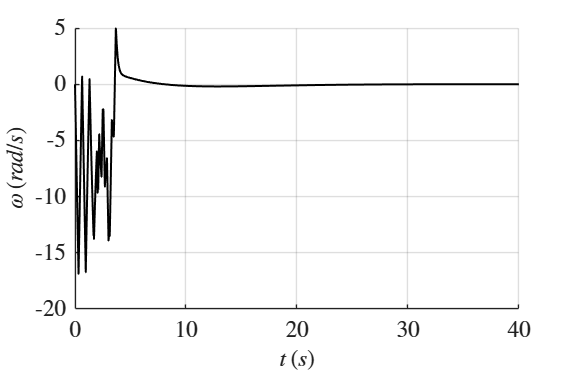


%% Figura 3 - Velocidade angular da roda

hfig = figure;

plot(t, x(3,:), 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\omega \, (rad/s)$', 'Interpreter', 'latex');

grid on;

fname = 'resultado_omega_simulado';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

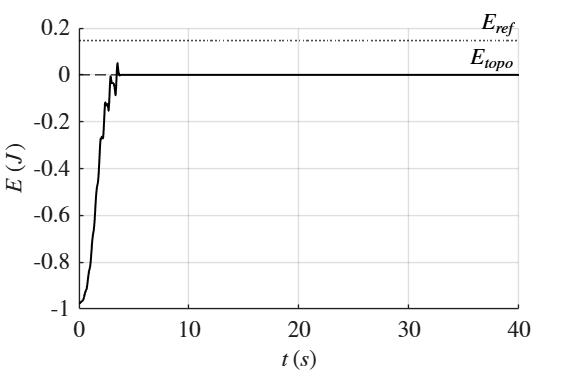


%% Figura 4 - Energia mecânica

hfig = figure;

plot(t, E, 'k-', 'LineWidth', 1.5);
hold on;
yline(Etopo, '--k', '$E_{topo}$', 'LineWidth', 1.2, 'Interpreter', 'latex');
yline(Eref, ':k', '$E_{ref}$', 'LineWidth', 1.2, 'Interpreter', 'latex');
hold off;

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$E \, (J)$', 'Interpreter', 'latex');

grid on;

fname = 'resultado_energia_simulado';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

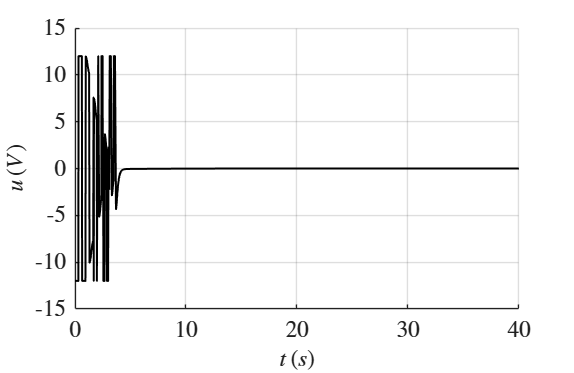


%% Figura 5 - Sinal de controle

hfig = figure;

plot(t, u, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$u \, (V)$', 'Interpreter', 'latex');

grid on;

fname = 'resultado_controle_simulado';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

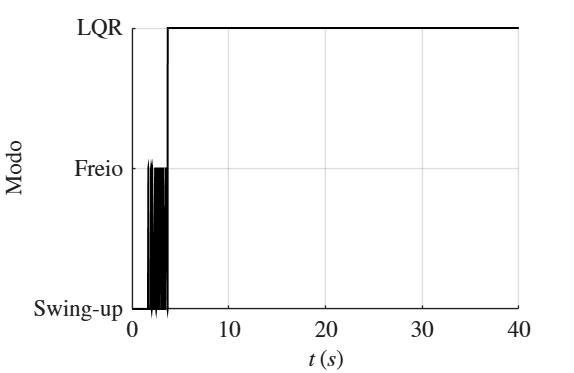


%% Figura 6 - Modo de controle

hfig = figure;

stairs(t, modo, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('Modo', 'Interpreter', 'latex');

yticks([0 1 2]);
yticklabels({'Swing-up', 'Freio', 'LQR'});

grid on;

fname = 'resultado_modo_simulado';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')


disp('Simulação concluída.');

Simulação concluída.


disp('PDFs gerados individualmente com sucesso.');

PDFs gerados individualmente com sucesso.
